# Problem 2

clc;
clear;
close all;

## Part A - See Written Portion

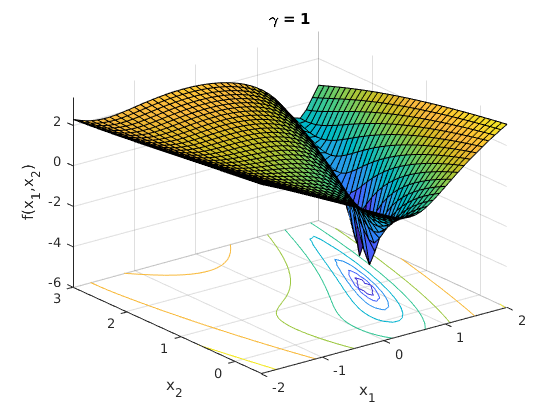

% Define function, gradient, and hessian
f = @(x1,x2,gamma) gamma*(x1.^2-x2).^2+(x1-1).^2;
g = @(x1,x2,gamma) [4*gamma*x1.*(x1.^2-x2)+2*x1-1; -2*gamma*(x1.^2-x2)];
H = @(x1,x2,gamma) [4*gamma*(x1.^2-x2)+8*gamma*x1.^2+2, -4*gamma*x1;...
                    -4*gamma*x1, 2*gamma];

% Draw 3D contour for gamma = 1 and gamma = 100
[xx1, xx2] = meshgrid(-2:0.1:2,-0.5:0.1:3);
figure;
surfc(xx1,xx2,log(f(xx1,xx2,1)));
title('\gamma = 1'); xlabel('x_{1}'); ylabel('x_{2}'); zlabel('f(x_{1},x_{2})');

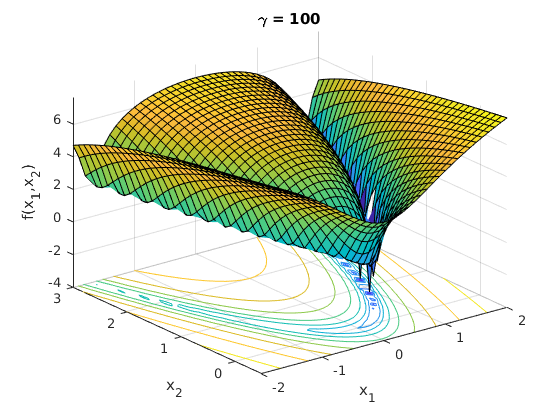

figure;
surfc(xx1,xx2,log(f(xx1,xx2,100)));    
title('\gamma = 100'); xlabel('x_{1}'); ylabel('x_{2}'); zlabel('f(x_{1},x_{2})');

## Part B

At $\gamma$ = 1, the function has few local minima concentrated in one area. Newton's method seems to converge faster than steepest descent. Even though steepest descent has yet to converge, it's solution is still relatively close to the Newton solution.

At $\gamma$ = 100, the function seems to have many local minima spread out across a large area. Here, steepest descent seems to perform definitively worse, where it jumps to many local minima points and still ultimately does not converge. Newton's method seems to proceed in a much more controlled manner, and converges relatively quickly.

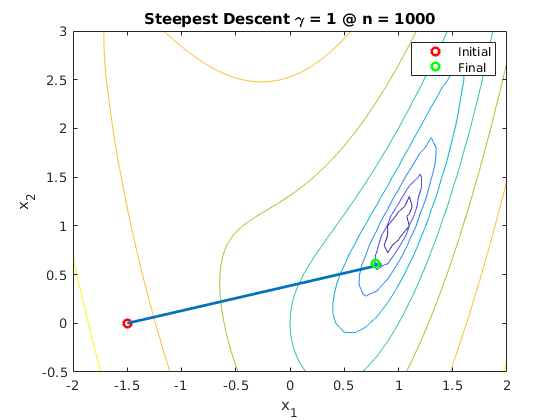

% set initial point
initial = [-1.5,0];

% Do steepest descent with gamma = 1
gamma = 1; % set gamma
v = zeros(1000,2); % save each update
v(1,:) = initial; % initial point

% Draw function contour
[xx1, xx2] = meshgrid(-2:0.1:2,-0.5:0.1:3);
figure;
contour(xx1,xx2,log(f(xx1,xx2,gamma)));
hold on;

% plot initial point
s = plot(v(1,1),v(1,2),'or','LineWidth',2);

% run steepest descent and draw each iteration (do exact line search)
ic = 1000;
for n=1:999
    pk = -g(v(n,1),v(n,2),gamma);
    fes = @(a) f(v(n,1)+a*pk(1),v(n,2)+a*pk(2),gamma);
    alpha = fminbnd(fes,1e-10,1);
    v(n+1,:) = v(n,:) + (alpha*pk)';
    if norm(pk) < 1e-6
        ic = n; % get convergence iteration
        break;
    end
end
plot(v(1:n+1,1),v(1:n+1,2),'LineWidth',2);

% plot final point
e = plot(v(n+1,1),v(n+1,2),'og','LineWidth',2);
hold off;

% plot config
legend([s,e],{'Initial','Final'})
title(['Steepest Descent \gamma = 1 @ n = ', num2str(ic)]);
xlabel('x_{1}'); ylabel('x_{2}');

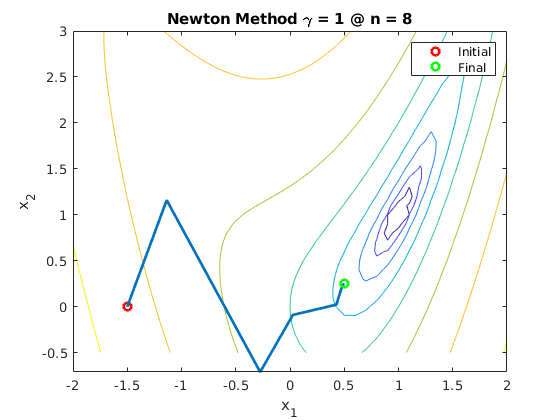

% Do Newton's method with gamma = 1
gamma = 1;
v = zeros(1000,2);
v(1,:) = initial;

% Draw function contour
[xx1, xx2] = meshgrid(-2:0.1:2,-0.5:0.1:3);
figure;
contour(xx1,xx2,log(f(xx1,xx2,gamma)));
hold on;

% plot initial point
s = plot(v(1,1),v(1,2),'or','LineWidth',2);

% run Newton's method and draw each iteration (do exact line search)
ic = 1000;
for n=1:999
    pk = -H(v(n,1),v(n,2),gamma)\g(v(n,1),v(n,2),gamma);
    fes = @(a) f(v(n,1)+a*pk(1),v(n,2)+a*pk(2),gamma);
    alpha = fminbnd(fes,1e-10,1);
    v(n+1,:) = v(n,:) + (alpha*pk)';
    if norm(pk) < 1e-6
        ic = n; % get convergence iteration
        break;
    end
end
plot(v(1:n+1,1),v(1:n+1,2),'LineWidth',2);

% plot final point
e = plot(v(n+1,1),v(n+1,2),'og','LineWidth',2);
hold off;

% plot config
legend([s,e],{'Initial','Final'})
title(['Newton Method \gamma = 1 @ n = ', num2str(ic)]);
xlabel('x_{1}'); ylabel('x_{2}');

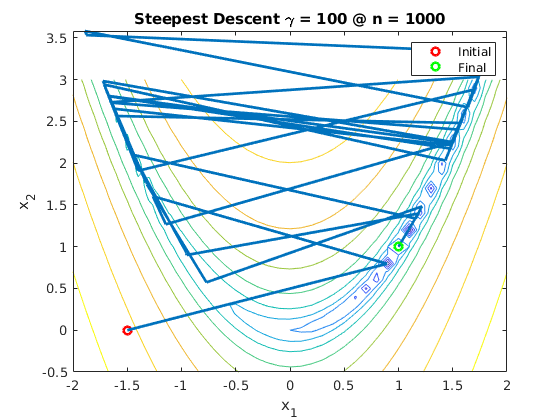

% Do steepest descent with gamma = 100
gamma = 100; % set gamma
v = zeros(1000,2); % save each update
v(1,:) = initial; % initial point

% Draw function contour
[xx1, xx2] = meshgrid(-2:0.1:2,-0.5:0.1:3);
figure;
contour(xx1,xx2,log(f(xx1,xx2,gamma)));
hold on;

% plot initial point
s = plot(v(1,1),v(1,2),'or','LineWidth',2);

% run steepest descent and draw each iteration (do exact line search)
ic = 1000;
for n=1:999
    pk = -g(v(n,1),v(n,2),gamma);
    fes = @(a) f(v(n,1)+a*pk(1),v(n,2)+a*pk(2),gamma);
    alpha = fminbnd(fes,1e-10,1);
    v(n+1,:) = v(n,:) + (alpha*pk)';
    if norm(pk) < 1e-6
        ic = n; % get convergence iteration
        break;
    end
end
plot(v(1:n+1,1),v(1:n+1,2),'LineWidth',2);

% plot final point
e = plot(v(n+1,1),v(n+1,2),'og','LineWidth',2);
hold off;

% plot config
legend([s,e],{'Initial','Final'})
title(['Steepest Descent \gamma = 100 @ n = ', num2str(ic)]);
xlabel('x_{1}'); ylabel('x_{2}');

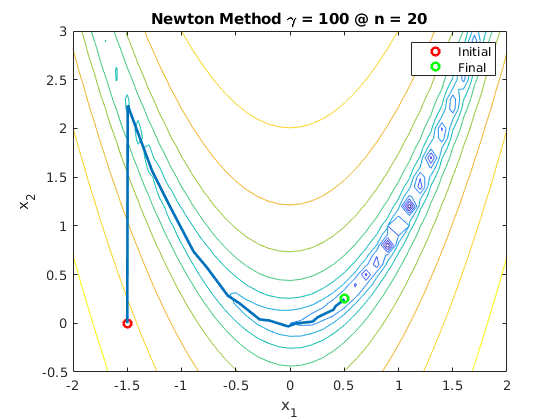

% Do Newton's method with gamma = 100
gamma = 100;
v = zeros(10000,2);
v(1,:) = initial;

% Draw function contour
[xx1, xx2] = meshgrid(-2:0.1:2,-0.5:0.1:3);
figure;
contour(xx1,xx2,log(f(xx1,xx2,gamma)));
hold on;

% plot initial point
s = plot(v(1,1),v(1,2),'or','LineWidth',2);

% run Newton's method and draw each iteration (do exact line search)
ic = 1000;
for n=1:999
    pk = -H(v(n,1),v(n,2),gamma)\g(v(n,1),v(n,2),gamma);
    fes = @(a) f(v(n,1)+a*pk(1),v(n,2)+a*pk(2),gamma);
    alpha = fminbnd(fes,1e-10,1);
    v(n+1,:) = v(n,:) + (alpha*pk)';
    if norm(pk) < 1e-6
        ic = n; % get convergence iteration
        break;
    end
end
plot(v(1:n+1,1),v(1:n+1,2),'LineWidth',2);

% plot final point
e = plot(v(n+1,1),v(n+1,2),'og','LineWidth',2);
hold off;

% plot config
legend([s,e],{'Initial','Final'})
title(['Newton Method \gamma = 100 @ n = ', num2str(ic)]);
xlabel('x_{1}'); ylabel('x_{2}');